clc;
close all;
clear;
format long;

B = 0.8e9; %带宽
f0 = 9.6e9;
f1 = 10.4e9;
f2 = 10e9;
fs= 40e9;  %采样频率 
Ts=1/fs; %

%采样间隔

T = 20e-6;   %调制时间50us
num = round(T / Ts); %周期采样点数


k = B / T;  %斜率
% t = (0:num-1) / fs; %时间序列
t = 0 : 1/fs : (num-1)/fs;

window = 1024;
overLap = 512;
nfft = 5000;



## 第一种信号:线性正调频

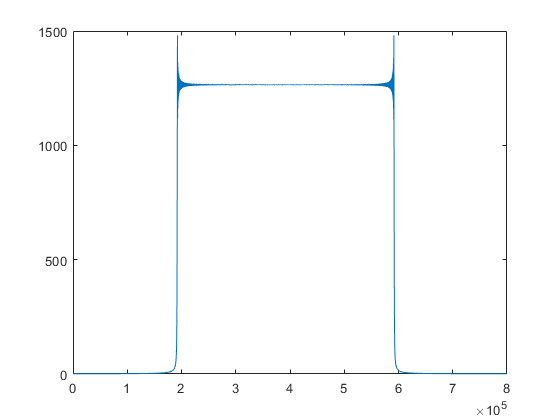


lfm_1 = exp(1j *2 * pi * (f0*t+0.5 * k *25*t.^2));
lfm_1 = lfm_1.';
plot(abs(fft(lfm_1)))

## 第三种信号：汉宁窗

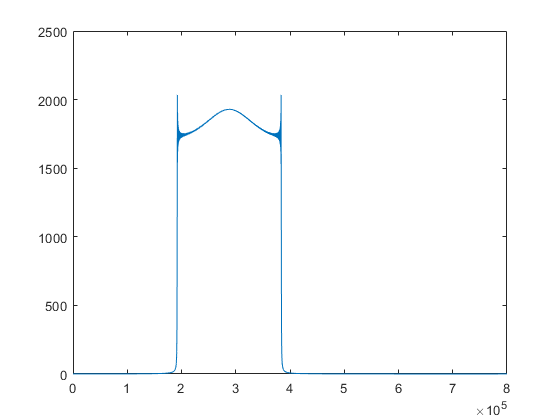

lfm_3 = exp(1j *2 * pi * (f0 * t + k*5*(1.2*t.^2-0.5*(T/2/pi)^2*cos(2*pi*t/T))));
lfm_3 = lfm_3.';
plot(abs(fft(lfm_3)))

## 第四种信号：负五次调频

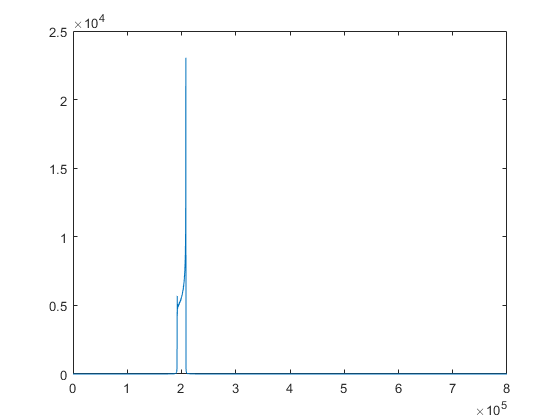

lfm_4 = exp(1j *2 * pi * (f0 * t + k*5*(1.2*t.^2-0.5*(T/2/pi)^2*cos(2*pi*t/T))));
lfm_4 = lfm_4.';
plot(abs(fft(lfm_4)))

## 第五种信号：正1.2次调频

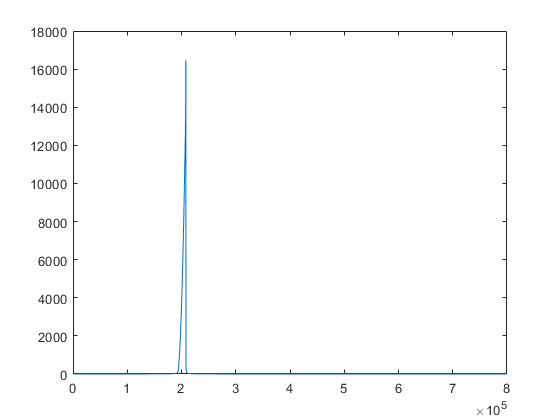

% ccc=(1+t'.*9e4)/1.4;

lfm_5 = exp(1j *2 * pi * (f0 * t + 1/1.20 * k * t.^1.20*(num/fs)^0.8));
lfm_5 = lfm_5.';
% lfm_5=lfm_5./ccc/1;
plot(abs(fft(lfm_5)))

## 第六种信号：负1.2次调频

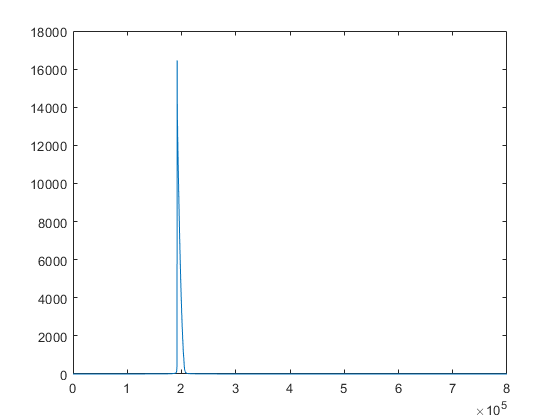

lfm_6 = exp(1j *2 * pi * (f1 * t - 1/1.20 * k * t.^1.20*(num/fs)^0.8));
lfm_6 = lfm_6.';
plot(abs(fft(lfm_6)))

 
f1 =
 
Empty sym: 0-by-1
 


## 尝试处理

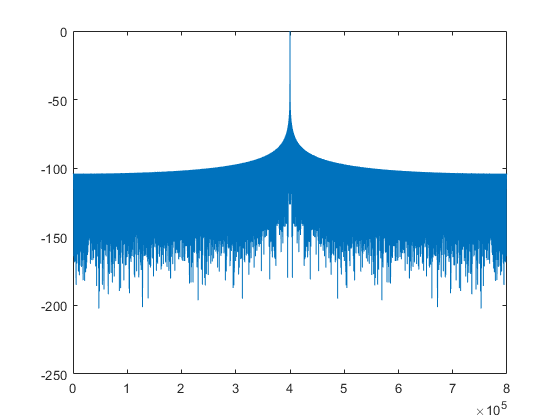

Hw=conj(fft(lfm_3));
Lfm_r=fft(lfm_3);
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/max(Q)))

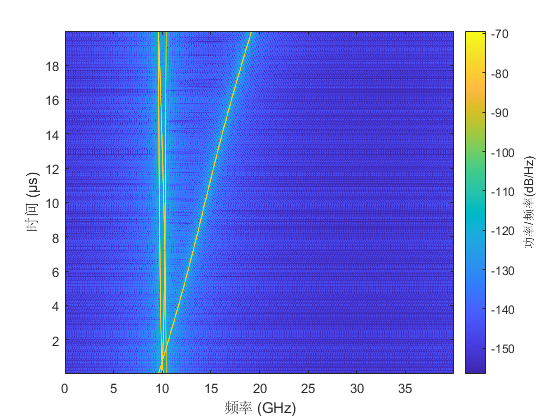


figure("name",'STFT_lfm_r2','NumberTitle','off');
spectrogram(lfm_3+lfm_4+lfm_5+lfm_6,window,overLap,nfft,fs);  